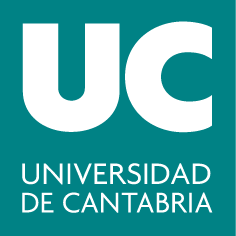

***Grado en Ingeniería en Tecnologías Industriales***

**G414: Álgebra y Geometría**

# **Guion MATLAB: Sistemas de ecuaciones lineales**

*Sara Pérez Carabaza (sara.perezcarabaza@unican.es)*

*Valvanuz Fernández Quiruelas (valvanuz.fernandez@unican.es). *

**Objetivos**

- Clasificación de sistemas de ecuaciones lineales

- Resolución de sistemas compatibles determinados

- Resolución de sistemas compatibles indeterminados

- Representación de sistemas lineales de dos ecuaciones en el plano

**Funciones de MATLAB utilizadas en este guion: **`rank, rref, null.`

## **1. Clasificación de sistemas lineales de ecuaciones**

Siempre que estemos frente a un sistema de ecuaciones lineales, lo primero que haremos es clasificarlo (y de hecho, si este es incompatible, no habrá nada más que hacer). 

Para determinar el tipo de sistema aplicaremos el teorema de Rouché-Fröbenius, y por tanto necesitamos el número de incógnitas, y el rango de la matriz de coeficientes y de la matriz ampliada.  

Opción 1: uso de la función rank: Veámoslo con el siguiente ejemplo:


$$\textstyle\left\{  \begin{array}{rcr}
			 x  + y - z & = & 0\\ 
			 3x + y -z & = & 2\\
			 4x - 2y + z & = & 3\\  
		 \end{array}\right.$$


A = [1 1 -1; 3 1 -1; 4 -2 1]; % matriz de coeficientes
[m, n]=size(A)% m: número de ecuaciones n: número de incógnitas
b = [0 2 3]';  % vector columna de términos independientes
Aamp = [A, b];  % matriz ampliada (concatenamos verticalmente el vector b )
[rank(A), rank(Aamp) n]  % R-F: sistema compatible determinado

Opción 2: uso de la función rref: Otra manera de calcular los rangos de la matriz de coeficientes $A$ y de la matriz ampliada$A^*$ es obteniendo la matriz escalonada reducida equivalente a $A^*$. Una vez tenemos el sistema escalonado reducido equivalente, determinamos el rango de $A$ y $A^*$ simplemente de contando el número de filas no nulas. En el ejemplo vemos que el rango de ambas matrices es 3.

Aampe=rref(Aamp)%Gauss Jordan, obtenemos matriz escalonada reducida

Una vez hemos comprobado que el sistema es compatible determinado (una única solución), veremos a continuación distintas formas de resolver este tipo de sistemas:

## **2. Resolución de sistemas lineales de ecuaciones**

### 2.1 Método de resolución: Cálculo de la matriz inversa 

Dado un sistema de ecuaciones lineal con matriz de coeficientes $A$ cuadrada $\left(m=n\right)$, si la matriz de coeficientes $A$ es regular $\left(\det \left(A\right)\not= 0\right)$, podemos utilizar la matriz inversa $A^{-1}$ para despejar el vector de incógnitas $\vec{x}$ en la ecuación matricial del sistema, $A\vec{x}=\vec{b}$. 

det(A) % comprobamos A regular -> SCD
inv(A)*b  % solución: (x=1, y=2, z=3)

### 2.2 Método de resolución con MATLAB: operador "\". 

Para este método necesitaremos la matriz de coeficientes  $A$ y el vector de términos independientes $\vec{b}$ . La operación `A\b` es una forma eficiente y general de encontrar una solución, y MATLAB selecciona automáticamente el método más apropiado para resolver el sistema basándose en las propiedades de la matriz *A*. Por ejemplo, si *A* es una matriz cuadrada, MATLAB podría optar por métodos directos como la descomposición LU.

Este método será muy buena opción para resolver un SCD

A\b  % solución: (x=1, y=2, z=3)

Sin embargo, debemos tener cuidado ya que si el sistema es SCI este método nos dará una solución particular (una de las infinitas posibles). Y si el sistema es sistema incompatible nos devolverá un vector, que obviamente no será solución.

### 2.3 Método de resolución: Gauss-Jordan

Este método nos permitirá resolver tanto SCD como SCI. Para dicho método calculamos la forma escalonada reducida por filas de la matriz ampliada del sistema. 

**Ejemplo SCD.** Continuamos con el ejemplo anterior. Importante no olvidarnos de pasar como argumento de entrada de rref la matriz ampliada (no la matriz de coeficientes):


$$\textstyle\left\{  \begin{array}{rcr}
			 x  + y - z & = & 0\\ 
			 3x + y -z & = & 2\\
			 4x - 2y + z & = & 3\\  
		 \end{array}\right.$$


rref(Aamp)  % solución: (x=1, y=2, z=3)

Una vez tenemos la forma escalonada reducida de la matriz ampliada del sistema, escribimos las ecuaciones del sistema equivalente. Las cuales nos dan directamente la solución:


$$\textstyle\left\{  \begin{array}{rcr}
			 x  & = & 1\\ 
			  y  & = & 2\\
			 z & = & 3\\  
		 \end{array}\right.$$


**Ejemplo SCI.** Resolvamos con GJ el siguiente SCI


$$
 \left\{ \begin{array}{rrrc}
    x_1 + x_2 + x_3 & = & 0\\ 
    2x_1 - x_2 + x_3 & = & 0 \\ 
    x_1 - 2x_2 & = & 0 \\ 
 \end{array}\right.
$$


A=[ 1 1 1 ; 2 -1 1 ; 1 -2 0];
b=[0 0 0]'
Aamp=[A b]
%gauss-jordan
rref(Aamp)

Hemos obtenido el siguiente sistema escalonado reducido equivalente


$$\left(\begin{array}{ccc|c}
     1 & 0 & 2/3 & 1\\  
     0 & 1 & 1/3 & 1\\  
     0 & 0 & 0 & 0\end{array}\right) \rightarrow
      \left\{ \begin{array}{rrrc}
         x_1 + 2/3x_3 & = & 0 \\ 
           x_2 + 1/3x_3 & = & 0 \\ 
          & 0= & 0 \\ 
      \end{array}\right.
$$


Siguiendo Rouché-Fröbenius, vemos que $\textrm{rg}\left(A\right)=\textrm{rg}\left(A^* \right)=2<n$, se trata de un SCI con un parámetro libre, que asignaremos a la variable de la columna no pivotal $x_3 =\alpha$. Para obtener la solución general simplemente sustituimos de abajo arriba (esta parte la haremos a mano):  $\vec{x}=\left( \begin{array}{c} -2/3  \alpha  \\ -1/3  \alpha \\  \alpha  \end{array} \right)=  \alpha \left( \begin{array}{c} -2/3 \\ -1/3 \\ 1 \end{array} \right)$

### 2.4 Método de resolución sistemas homogéneos: función null

Una característica importante de los sistemas lineales homogéneos es que son siempre compatibles, ya que tienen al menos la solución trivial (siendo esta la solución de los sistemas homogéneos compatibles determinados). 

MATLAB cuenta con una función específica para resolver directamente sistemas homogéneos: `null`*. * Solo requiere como entrada la matriz de coeficientes del sistema, $A$ al asumir que el vector de términos independientes del sistema es nulo. 

Esta función es muy útil, pero hay que saber cómo interpretar el resultado que devuelve.

**Ejemplo 1. **En el caso de **sistemas homogéneos determinados** como el que utilizamos en el primer ejemplo de este apartado, *null* devolverá una matriz vacía [], lo que indica que la única solución del sistema es la trivial.


$$B:\textstyle\left\{  \begin{array}{rcr}
			 x - 3y + 4z & = & 0\\ 
			 x - 2y + 5z & = & 0\\
			 2x - y - 3z & = & 0\\  
		 \end{array}\right.$$


B=[1 -3 4; 1 -2 5; 2 -1 3]
null(B, 'r')  % sol. trivial: (x=0, y=0, z=0)

**Ejemplo 2. **En el caso de** sistemas homogéneos compatibles indeterminados** devolverá un vector por cada parámetro libre. Y la solución de sistema lineal homogéneo será la combinación lineal de todos los vectores devueltos por la función `null`.


$$
 \left\{ \begin{array}{rrrc}
    x_1 + x_2 + x_3 & = & 0\\ 
    2x_1 - x_2 + x_3 & = & 0 \\ 
    x_1 - 2x_2 & = & 0 \\ 
 \end{array}\right.
$$


A=[ 1 1 1 ; 2 -1 1 ; 1 -2 0];
b=[0 0 0]'
Aamp=[A b]
null(A,'rational')%la opción rational o 'r' no es obligatoria, pero es preferible 

La solución general del SCI homogéneo es la combinación lineal del un único vector devuelto por la funcion null: $\vec{x}=  \alpha \left( \begin{array}{c} -2/3 \\ -1/3 \\ 1 \end{array} \right)$

## **3. Representación de sistemas lineales de ecuaciones en el plano**

Una ecuación con dos incógnitas representa una recta en el plano. Un sistema de *m* ecuaciones con *n*=2 incógnitas consiste en hallar los puntos comunes a las m rectas. 


$$   \begin{array}{rcr}
  a_{11}x + a_{12}y & = & b_1\\ 
  a_{21}x + a_{22}y  & = & b_2\\
  \end{array}$$


Como ya sabemos, se pueden dar 3 situaciones: las rectas no tienen ningún punto en común (SI), las rectas tienen 1 punto (x,y) en común (SCD), o las rectas tienen infinitos puntos en común (SCI).

Podemos clasificar el tipo de sistema representando gráficamente el sistema de ecuaciones. Para ello usaremos la función `plot` de Matlab. Para pintar dos gráficas en la misma figura usamos el comando `hold on`, que permite pintar una gráfica encima de otra.

Además, esta representación del sistema no solo nos permite clasificar el sistema, sino que es otro método de resolución. Este método de resolución, denominado **método gráfico**, nos permite obtener una solución aproximada del sistema.

**Ejemplo**. Sistema de dos ecuaciones con dos incógnitas:


$$      \left\{ \begin{array}{rrc}
          - 3x_1 + x_2 & = & 2 \\ 
         x_1 + x_2 & = & 1 \\ 
      \end{array}\right.$$


x=-2:0.1:3; %damos valores a la variable x (desde -2 hasta 3 espaciados 0.1)
y1=3*x+2;
y2=-x+1;
figure; %nueva figura
plot(x,y1)
hold on %para que represente encima del anterior plot y no lo borre
plot(x,y2)
grid on %para visualizar la rejilla o malla en la figura
xlabel('eje x');%añade etiqueta al eje x
ylabel('eje y');%añade etiqueta al eje y

Gráficamente podemos obtener una solución aproximada. Al resolver el sistema comprobamos que el punto de corte es (-1/4,1.25)

A=[-3 1; 1 1];
b=[ 2 1]';
x=A\b

## 4. Ejercicios propuestos

**Ejercicio 1:**

Clasifica el siguiente sistema mediante el teorema del rango. Representa gráficamente el sistema en el plano y comprueba si la clasificación obtenida coincide con la representación gráfica.


$$      \left\{ \begin{array}{rrc}
         2x + 3y & = & 7 \\ 
         7x + 9y& = & 5 \\ 
          - x + 10y& = & 2 \\ 
      \end{array}\right.
$$


**Ejercicio 2:**

Comprueba que el siguiente sistema es compatible determinado y resuélvelo utilizando los 4 métodos que hemos visto para este tipo de sistemas. Verifica que la solución que has obtenido es la correcta.


$$\textstyle\left\{  \begin{array}{rcr}
			 -x -2y - 3z & = & -3\\ 
			 2x + 3y + 2z & = & -2\\
			 x + 2y + 4z & = & 
3\\  
		 \end{array}\right.$$


## Bibliografía 

- Guiones para Matlab realizados por Rodrigo García Manzanas y Ruth Carballo Fidalgo para la asignatura de Álgebra y Geometría del Grado en Ingeniería Civil.